## **GENERATING SYNTHETIC DATA FOR A SIGNAL  **

% Define parameters
Fs = 50; % sampling frequency
T = 10; % total time duration
N = Fs * T; % number of observations
f1 = 10; % frequency 1
f2 = 17; % frequency 2
t = linspace(0, T, N); % time vector

% Generate signal
y = sin(2*pi*f1*t) + sin(2*pi*f2*t);

% Randomly sample signal
missing_percentage = 0.10; % 10% missing data
num_samples = round(N*(1-missing_percentage));
rand_indices = randperm(N, num_samples);
y_sample = y(rand_indices);

% Generate synthetic data
t = t(rand_indices); % time values

% Sort t and y_sample in increasing order of time
[t, idx] = sort(t);
y_sample = y_sample(idx);

% Add noise to the signal
SNR = 10; % Signal-to-Noise Ratio
y_var = var(y_sample); % variance of signal
noise_var = y_var / (10^(SNR/10)); % variance of noise based on desired SNR
noise = sqrt(noise_var) * randn(size(y_sample)); % generated noise

% Signal with added noise
y_obs = y_sample + noise;

% Split the data into training and testing sets
train_ratio = 0.8; % 80% of the data is used for training
num_train_samples = round(num_samples * train_ratio);
y_train = y_obs(1:num_train_samples);
t_train = t(1:num_train_samples);
y_test = y_obs(num_train_samples+1:end);
t_test = t(num_train_samples+1:end);
y_train_centred = (y_train - mean(y_train)) / std(y_train);
y_test_centred = (y_test - mean(y_test)) / std(y_test);

% Define frequencies at which to compute periodogram
frequencies = linspace(0,Fs/2,1000);

% Set hyperparameters for gradient descent
max_iterations = 1000;
learning_rate = 0.0001;

## CALCULATING THE ESTIMATES USING THE LOMB-SCALE PERIODOGRAM FUNCTION

% Train the model on the training data
[a_syn, b_syn] = LS_periodogram(y_train_centred, t_train, frequencies, max_iterations, learning_rate);
% Initialize periodogram
periodogram = zeros(size(frequencies));
% Calculate periodogram value for current frequency
for i = 1:length(frequencies)
    periodogram(i) = (a_syn(i)^2 + b_syn(i)^2);
end

## PLOTTING THE LOMB-SCALE PERIODOGRAMS

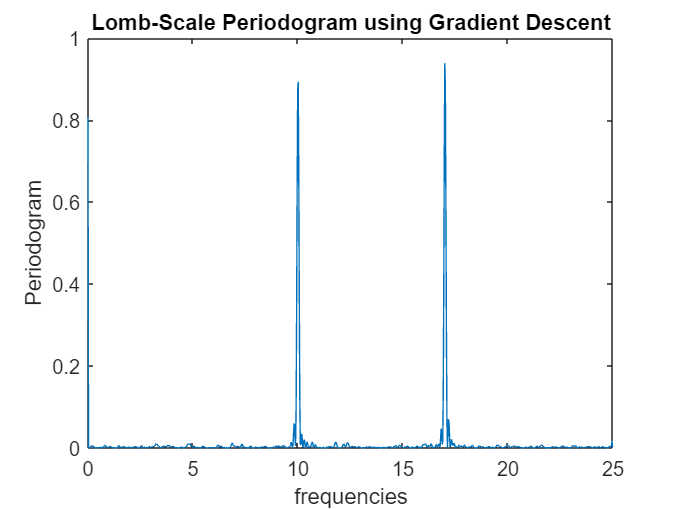

figure;
plot(frequencies,periodogram)
title('Lomb-Scale Periodogram using Gradient Descent')
xlabel('frequencies');
ylabel('Periodogram');

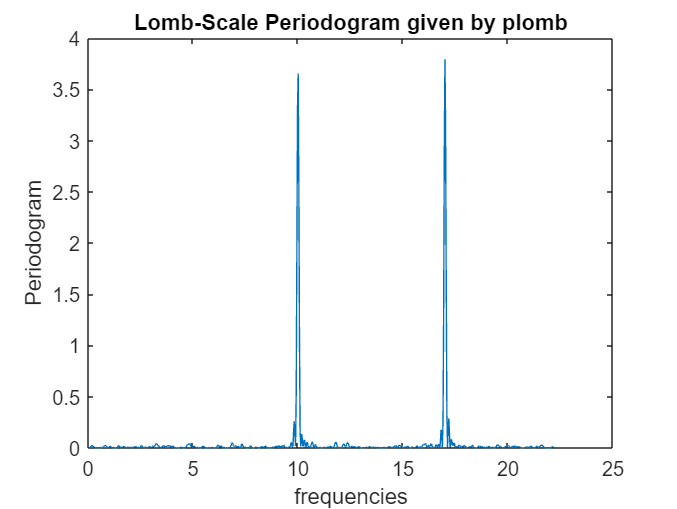

[p,f] = plomb(y_train_centred,t_train);
plot(f,p)
title('Lomb-Scale Periodogram given by plomb')
xlabel('frequencies');
ylabel('Periodogram');

## FORECASTING THE SIGNAL FOR TEST DATASET USING ESTIMATES OBTAINED FROM LS PERIODOGRAM

% Forecast the signal for the test data
    y_forecast = zeros(size(t_test));
for i = 1:length(frequencies)
    y_forecast =  y_forecast + a_syn(i) * cos(2 * pi * frequencies(i) * t_test) + b_syn(i) * sin(2 * pi * frequencies(i) * t_test);
end

% Calculate the errors on the test data
error = y_test - y_forecast;

% Normalized Mean Square Error (NMSE)
nmse = sum(error.^2) / sum(y_test.^2);

% Mean Absolute Percentage Error (MAPE)
mape = mean(abs(error ./ y_test)) * 100;

% Display the errors
fprintf('Normalized Mean Square Error: %.4f\n', nmse);

Normalized Mean Square Error: 0.9306


fprintf('Mean Absolute Percentage Error: %.2f%%\n', mape);

Mean Absolute Percentage Error: 146.46%


## **FITTING ARIMA MODEL TO THE SYNTHETIC DATA**

% Fit an ARIMA model to the training data
% Define the ARIMA model
Mdl = arima(1,1,1);

% Estimate the parameters
EstMdl = estimate(Mdl, y_train');

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic      PValue  
                ___________    _____________    __________    __________

    Constant    -0.00087213     0.00078408        -1.1123        0.26601
    AR{1}         -0.030067       0.045347       -0.66305         0.5073
    MA{1}                -1      0.0091928        -108.78              0
    Variance         1.1459        0.10504          10.91     1.0382e-27




% Use the fitted model to forecast the values of the test data
[yF, yMSE] = forecast(EstMdl, length(y_test), 'Y0', y_train');

% Calculate the errors
errors = y_test' - yF;

% Normalized Mean Square Error (NMSE)
nmse = sum(errors.^2) / sum(y_test'.^2);

% Mean Absolute Percentage Error (MAPE)
mape = mean(abs(errors ./ y_test')) * 100;

% Display the errors
fprintf('Normalized Mean Square Error: %.4f\n', nmse);

Normalized Mean Square Error: 1.0083


fprintf('Mean Absolute Percentage Error: %.2f%%\n', mape);

Mean Absolute Percentage Error: 192.55%


The given metrics NMSE is computed as the average of the squared differences between the predicted and actual values, normalized by  the variance of the actual values. The NMSE values can range from 0 to infinity, with 0 indicating an ideal  match. On the other hand, MAPE is calculated as the mean of the absolute differences between the predicted  and actual values, divided by the actual values, and then multiplied by 100 to convert it into a percentage. The  MAPE values can range from 0% to infinity, with 0% indicating an ideal match. The advantage of MAPE is that it  presents errors as a percentage of the actual values, which makes it easier to comprehend the error magnitude.  However, it has a drawback in that it can lead to undefined or infinite values when the actual value is zero.

As we can see that after comparing perfomances of both models (Lomb-Scargle and ARIMA), in the both metric (NMSE and MAPE). Lomb-Scargle periodogram has lower NMSE and MAPE values compared to ARIMA.

This is due to the fact that Lomb-Scargle periodogram essentially tries to fit the sinusodal model to any given data, and as the synthetic data generated is also consisting of sinusoids. So, Lomb-Scargle periodogram perfectly detects the underlying frequencies and forecasts the signal also to a good extent.

## **LOMB-SCALE PERIODOGRAM FUNCTION**

function [a, b] = LS_periodogram(y, t, frequencies, max_iterations, learning_rate)
    
    % Initialize parameters a and b outside the loop
    a = zeros(length(frequencies), 1); % random initialization
    b = zeros(length(frequencies), 1); % random initialization
    
    % Loop through each frequency
    for f = 1:length(frequencies)
        % Random initialization for each frequency
        a(f) = rand();
        b(f) = rand();
        
        % Gradient descent to minimize objective function
        for iter = 1:max_iterations
            % Compute gradients
            grad_a = (-2) * sum((y- a(f)*cos(2*pi*frequencies(f)*t) - b(f)*sin(2*pi*frequencies(f)*t)).*(cos(2*pi*frequencies(f)*t)));
            grad_b = (-2) * sum((y - a(f)*cos(2*pi*frequencies(f)*t) - b(f)*sin(2*pi*frequencies(f)*t)).*(sin(2*pi*frequencies(f)*t)));
            
            % Update parameters
            a(f) = a(f) - learning_rate * grad_a;
            b(f) = b(f) - learning_rate * grad_b;
        end
    end
end  